## Mass of the Comma Cluster

## Problem Statement

Determine the mass of the comma cluster in Solar masses. The mass is given by 


$$M = \frac{3\pi}{G}\sigma_{vr}^{2}d$$


where $G = 0.004301$ is the gravitational constant in  $\text{pc}\ \left( \frac{\text{Km}}{\text{s}} \right)^{2}/M_{\text{sol}$ and $d$ is the harmonic mean of the projected separations of the galaxies. $\sigma_{vr}$ is the dispersion in the radial velocities. $D = 93 \times 10^{6}\ \text{pc}$ is the mean distance to the cluster from our location. 

## Procedure

There are four parts to the exercise.

 Partial solution is provided in some cases. Erase out the XXXXX strings that appear in the code and replace them by your own code. This live script is broken down into sections. To run the code belonging to a section,  Press CTRL+ ENTER. Do not run any sections unless you have the full code ready for that section; you can try out parts of your code from a separate m-file and the the Matlab shell. 

The partial code is provided as a hint; you can also erase out everything and write out your own code. Some graphs and calculated values have been retained in this script, they are for comparing your results (You can copy this script and work off from that copy instead, or use the pdf file for reference.)

### Data set comprehension

Read in a data file` comma.txt `containing the coordinates of the galaxies in the **3rd**	and **4th** columns (in *arc minutes*) and the radial velocities of these galaxies (in *Km/sec*) their** 6th**	column. How many galaxies are covered in this data-set? (Print)

clc; clear
G      = 0.004301; %in pc*(Km/s)^2/MSol
dcomma = 93e6;%distance to cluster in pc
load('coma.txt');
nGxy   = length(coma);
fprintf('\n number of galaxies: %d\n',nGxy)


 number of galaxies: 281


### Plotting the Galaxy distribution and their radial velocities

Extract the $x,y,v_{r}$ data to three vectors and plot the distribution of galaxies in the sky. Also plot their radial velocities  versus their distance from the center of the cluster (0,0)

First, Plot the distribution of the galaxies.

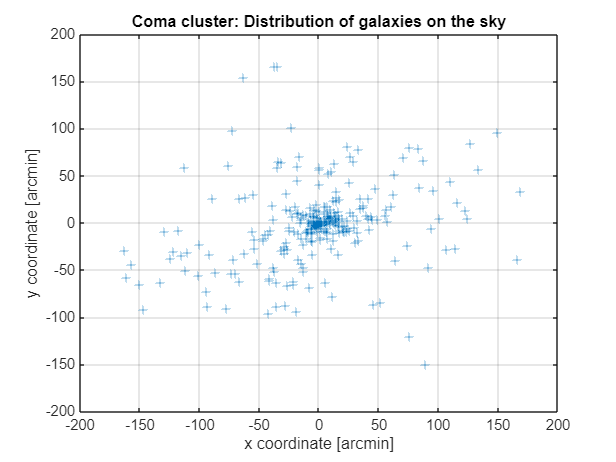

xx     = coma(:,3);
yy     = coma(:,4);
vr     = coma(:,6);
%Plot distribution of clusters
figure(1);
plot(xx, yy, '+');
title('Coma cluster: Distribution of galaxies on the sky');
xlabel('x coordinate [arcmin]');
ylabel('y coordinate [arcmin]');
grid on;

Next plot the radial velocities

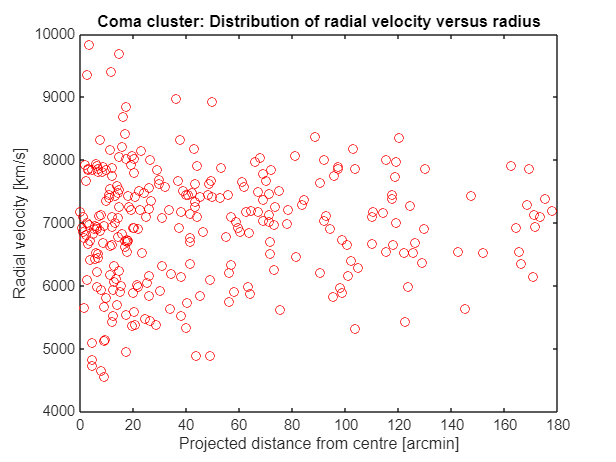

figure(2);
r = sqrt((xx.^2)+(yy.^2)); % Distance.
plot(r, vr, 'or');
title('Coma cluster: Distribution of radial velocity versus radius');
xlabel('Projected distance from centre [arcmin]');
ylabel('Radial velocity [km/s]');
grid off;

### Harmonic mean of the projected separations

 Calculate the harmonic mean of the projected separations according to  the following   algorithm (use the variables `ii` and `jj` n place of `i` and `j`):

`-----------------------------------------------------------`

`summ=0`

`for i in 1 to n`

`    for j in 1 to n`

`        if i `$\neq$  j,  

                   //* calculate* $r_{ij}$, *the separation between the i th  and j th galaxies*

`          summ`=`summ` + $\frac{1}{r_{ij}}$

`        end if`

`    end inner for` 

`end outer for`


$$d = n(n - 1)/\text{summ}$$
 

$d = D\text{sin}\left( \frac{\pi\ d}{180 \times 60} \right)$ // *To finally convert from arcmin to pc *

`--------------------------------------------------------`

% Harmonic mean of projected separations
sumn = 0 ;
for i = 1:nGxy
    for j = 1:nGxy
        if i ~= j
            dist = sqrt((xx(j)-xx(i)).^2 + (yy(j)-yy(i)).^2);
            sumn = sumn + (1/dist);
        end
    end
end

D = 93e6;

d = (nGxy*(nGxy-1))/(sumn);
d = D * sin((pi*d)/(180*60));
fprintf('\n Harmonic mean of projected separations (in pc): %d\n',d)


 Harmonic mean of projected separations (in pc): 8.513282e+05


### Calculation of the virial Mass

A few lines of code is needed to get the virial mass. What is the  result in Solar mass ? (Print)

% Calculate the dispersion in radial velocities
sigma_vr = sum((vr - mean(vr)).^2)/nGxy;
% Calculate the mass of the cluster
MCl = ((3*pi)/(G))*(sigma_vr)*d;
%TotalMCL = sum(MCl);
fprintf('\nMass of Comma Cluster = %e MSol\n',MCl);


Mass of Comma Cluster = 1.557174e+15 MSol


% Uncomment and Edit this section after completing the enire assignment and
% before generating the output pdf.

s=date;
Name='Tathagata Karmakar (Roll 122)';
disp( ['Saved on: ' s ' by ' Name ])

Saved on: 10-Feb-2026 by Tathagata Karmakar (Roll 122)
